# Weiner filtering

### Data Construction

data = load("idealECG.mat");

disp(fieldnames(data));

    {'idealECG'}




% y_i is the ideal signal
y_i = data.idealECG; 

disp(y_i);

  Columns 1 through 3,276

   -0.1850   -0.1550   -0.1450   -0.1350   -0.1050   -0.0950   -0.0950   -0.0650   -0.0550   -0.0250   -0.0050    0.0250    0.0450    0.0750    0.0950    0.1050    0.1050    0.1150    0.1050    0.0750    0.0450    0.0050   -0.0450   -0.0750   -0.1050   -0.1150   -0.1250   -0.1250   -0.1250   -0.1250   -0.1250   -0.1350   -0.1350   -0.1350   -0.1350   -0.1250   -0.1250   -0.1250   -0.1350   -0.1350   -0.1550   -0.1450   -0.1650   -0.1650   -0.1550   -0.1750   -0.1650   -0.1450   -0.0950   -0.0450   -0.0550   -0.1050   -0.1050   -0.1650   -0.1950   -0.2050   -0.2250   -0.2150   -0.2150   -0.2150   -0.2050   -0.2050   -0.2150   -0.2150   -0.2150   -0.2150   -0.1950   -0.1750   -0.2650   -0.4350   -0.2350    0.3850    1.3250    1.4950    0.3550   -0.5150   -0.5650   -0.3650   -0.2250   -0.2050   -0.2150   -0.2350   -0.2250   -0.2250   -0.2150   -0.1950   -0.1950   -0.2050   -0.1750   -0.1850   -0.1750   -0.1650   -0.1450   -0.1250   -0.1150   -0.1050   -0.0850   


M = length(y_i); % Length of the ECG signal
Fs = 500;
time = (0:M-1)/500; % time vector

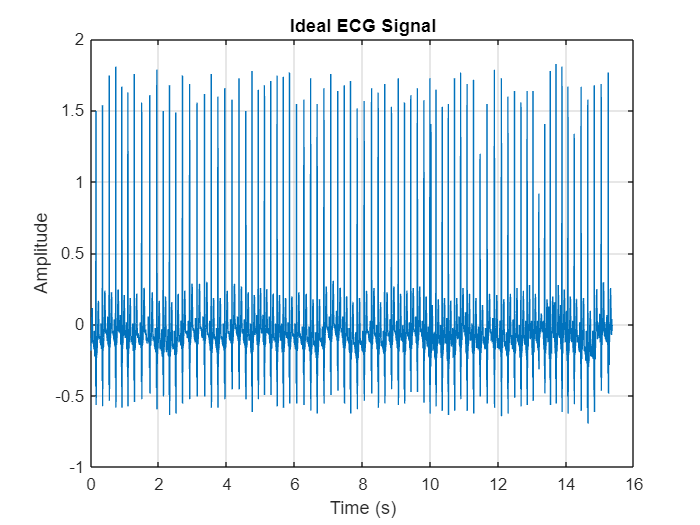

% Plot y_i
figure;
plot(time, y_i);
xlabel('Time (s)');  
ylabel('Amplitude');        
title('Ideal ECG Signal');  
grid on;   

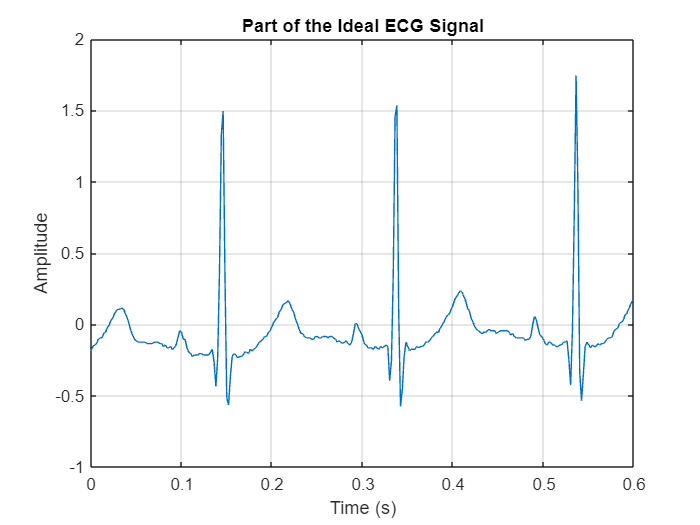


% Plot a part of the y_i
figure;
t = 1:300;
plot(time(t), y_i(t));
xlabel('Time (s)');  
ylabel('Amplitude');        
title('Part of the Ideal ECG Signal');  
grid on;   

% White Gaussian Noise
SNR = 10;
rng(0);
y_with_wg = awgn(y_i, SNR, "measured"); % Signal with White Gaussian Noise

% 50Hz noise
n_50 = 0.2 * sin(2 * pi * 50 * time);

% Noisy ECG Signal
x = y_with_wg + n_50;

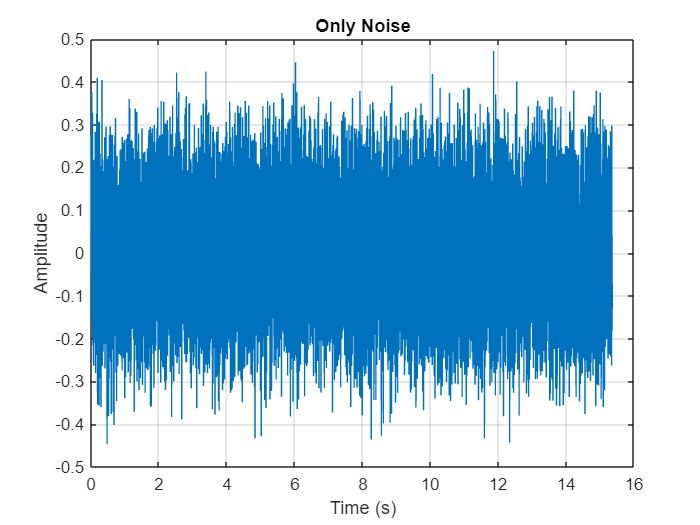

% Noise only
only_noise = x - y_i;

% Plot a part of the noisy ECG
figure;
plot(time, only_noise);
xlabel('Time (s)');  
ylabel('Amplitude');        
title('Only Noise');  
grid on; 

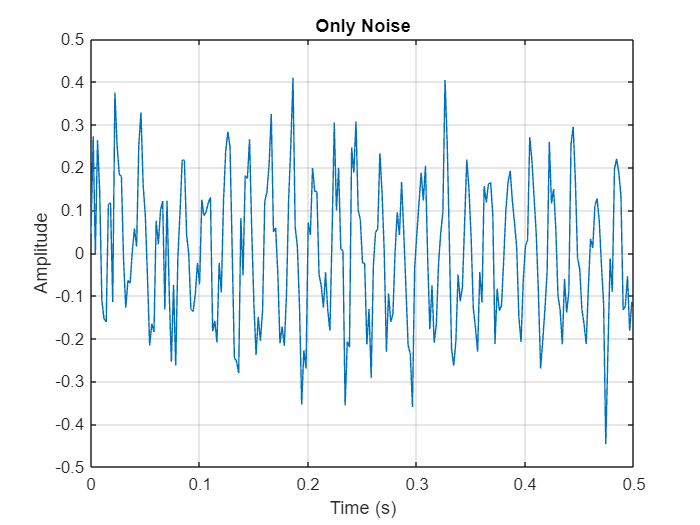


t = 1:250;
figure;
plot(time(t), only_noise(t));
xlabel('Time (s)');  
ylabel('Amplitude');        
title('Only Noise');  
grid on; 

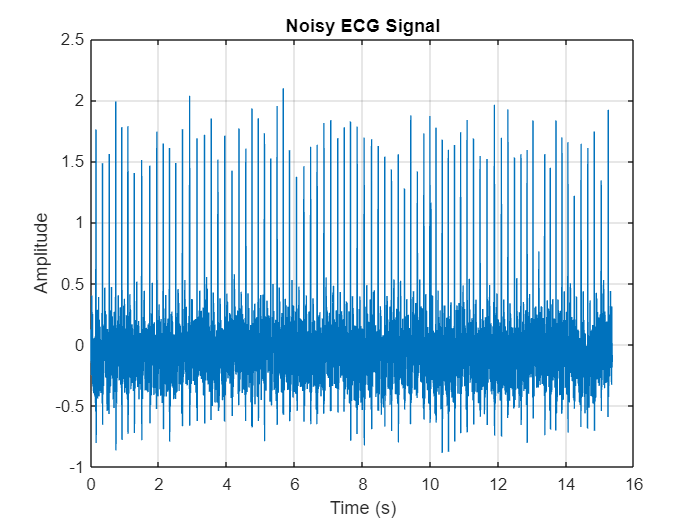

% Plot the Noisy ECG Signal
figure;
plot(time, x);
xlabel('Time (s)');  
ylabel('Amplitude');        
title('Noisy ECG Signal');  
grid on;

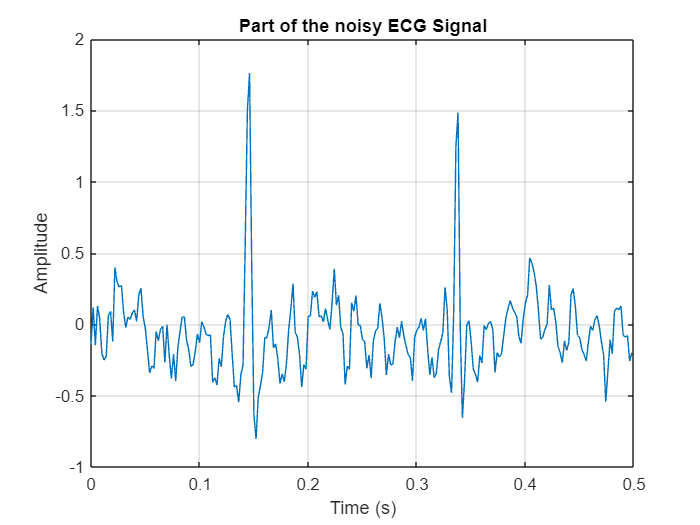

% Plot a part of the noisy ECG
figure;
t = 1:250;
plot(time(t), x(t));
xlabel('Time (s)');  
ylabel('Amplitude');        
title('Part of the noisy ECG Signal');  
grid on;   

### 1.1 Discrete time-domain implementation of the Wiener filter

#### Part 1

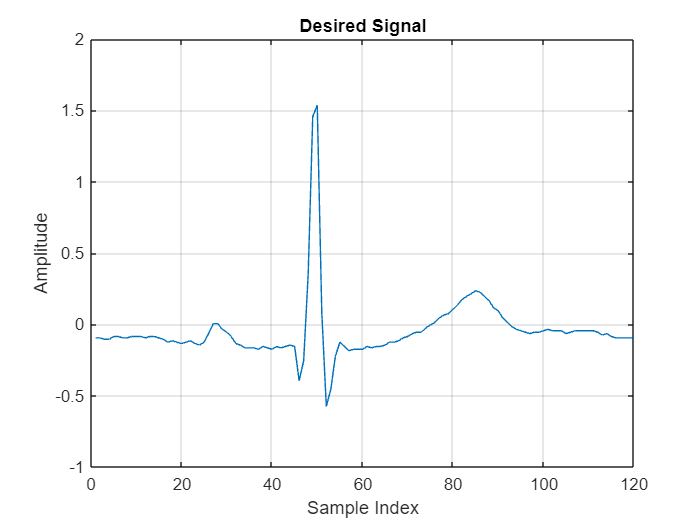

% Desired Signal
signal = 121:240;

y_i_1 = y_i(signal);

figure;
plot(y_i_1);
grid on;
xlabel('Sample Index');
ylabel('Amplitude');
title('Desired Signal');

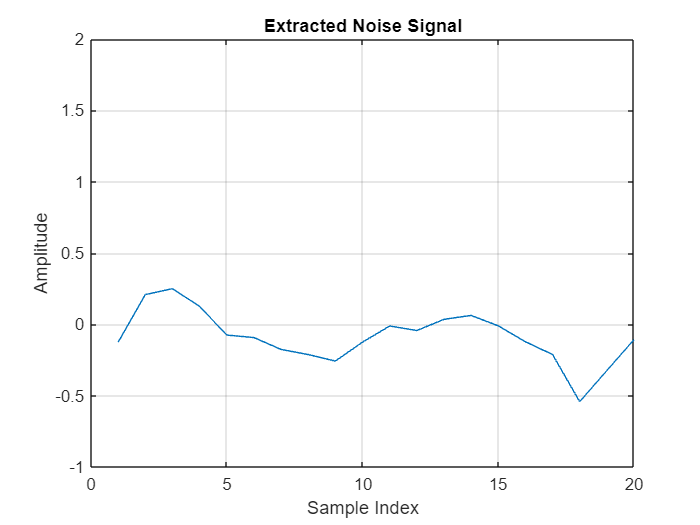

% Define the range for the noise signal
Noise_ = 221:240;

Noise_signal = x(Noise_);

figure;
% Plot the isoelectric segment
plot(Noise_signal);

% Set the y-axis limits from -1 to 2
ylim([-1 2]);

xlabel('Sample Index');
ylabel('Amplitude');
title('Extracted Noise Signal');
grid on;

W = wiener_opt_weights(y_i_1, Noise_signal, 20);

% Filter x using wiener filter

% Make E[x] to zero
x_ = x - mean(x);

filtered_signal = filter(W, 1, x_)

filtered_signal =    -0.0684    0.1185   -0.0795    0.1520    0.0191   -0.0653   -0.1930   -0.1029    0.0487    0.1684   -0.1177    0.3471    0.1638    0.3180    0.1668    0.1719    0.0360    0.1993    0.0141    0.2631   -0.0127    0.0798    0.1001    0.1887    0.0873    0.0458   -0.0878   -0.0793   -0.2061   -0.1097   -0.0151   -0.1303   -0.0393   -0.0750   -0.1985    0.0178   -0.0992   -0.2050   -0.0652   -0.2719   -0.0601   -0.0620   -0.0121    0.0006   -0.1055   -0.1385   -0.1198   -0.1678   -0.0063   -0.0241


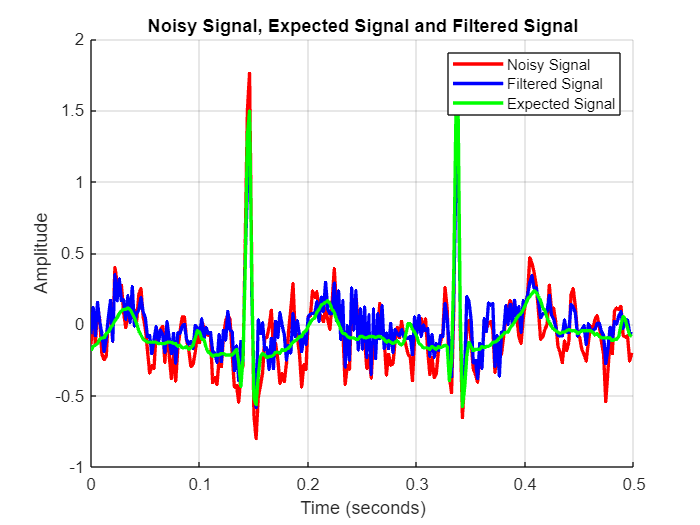

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(time(t_), filtered_signal(t_), 'b-', 'DisplayName', 'Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(time(t_), y_i(t_), 'g-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

% Find the optimum order filter
MSEs = zeros(1, 500);  % Preallocate array for efficiency
for i = 1:500
    W_ = wiener_opt_weights(y_i_1, Noise_signal, i);
    filtered_signal_ = filter(W_, 1, x_);
    MSEs(i) = mean((y_i - filtered_signal_).^2);  % Store MSE in the i-th location
end
disp(MSEs);

    0.0218    0.0217    0.0215    0.0212    0.0201    0.0192    0.0191    0.0191    0.0189    0.0181    0.0176    0.0175    0.0175    0.0173    0.0175    0.0167    0.0167    0.0168    0.0167    0.0182    0.0161    0.0162    0.0163    0.0163    0.0160    0.0158    0.0157    0.0157    0.0157    0.0156    0.0155    0.0155    0.0155    0.0156    0.0152    0.0150    0.0148    0.0149    0.0149    0.0148    0.0143    0.0143    0.0143    0.0144    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0144    0.0144    0.0143    0.0142    0.0142    0.0142    0.0142    0.0142    0.0141    0.0141    0.0141    0.0141    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144

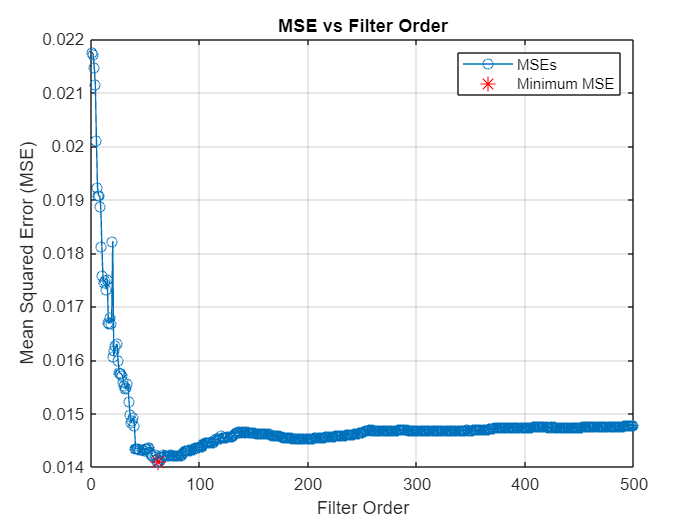

% Find the minimum value in MSEs and its index
[minMSE, minIndex] = min(MSEs);

% Plot MSEs
figure;
plot(1:500, MSEs, '-o');  % Plot MSEs against iterations (1 to 100)
xlabel('Filter Order');
ylabel('Mean Squared Error (MSE)');
title('MSE vs Filter Order');
grid on;

% Highlight the minimum MSE on the plot
hold on;
plot(minIndex, minMSE, 'r*', 'MarkerSize', 10);  % Red star at the minimum point
legend('MSEs', 'Minimum MSE');
hold off;


% Display the minimum MSE and its index
disp(['Minimum MSE: ', num2str(minMSE), ' at iteration ', num2str(minIndex)]);

Minimum MSE: 0.014107 at iteration 62


M_optimum = 62;
W_optimum = wiener_opt_weights(y_i_1, Noise_signal, M_optimum);
fvtool(W_optimum, 1);

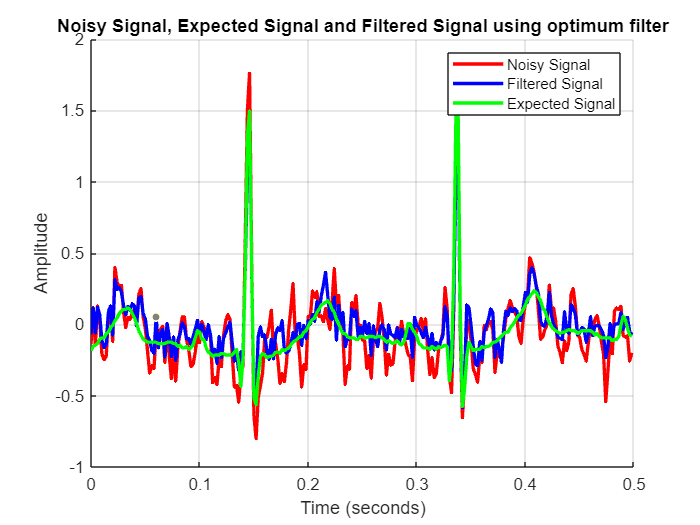

filtered_signal_opt = filter(W_optimum, 1, x_);

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(time(t_), filtered_signal_opt(t_), 'b-', 'DisplayName', 'Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(time(t_), y_i(t_), 'g-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal using optimum filter');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

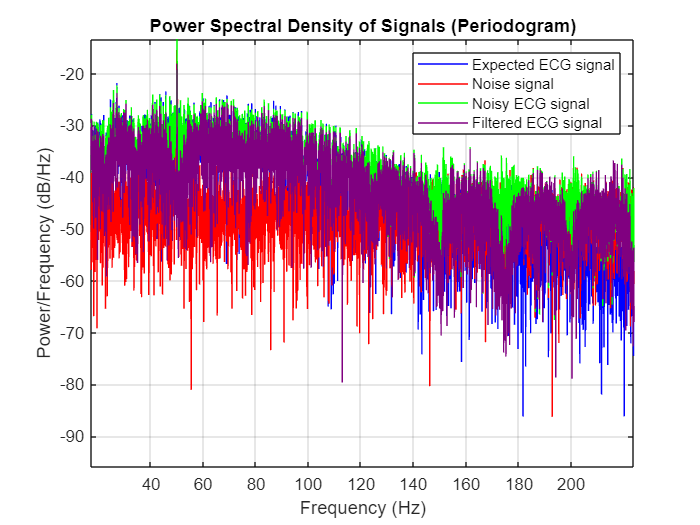

% Calculate the periodogram (PSD) for each signal
[psd1, f1] = periodogram(y_i, [], [], Fs);
[psd2, f2] = periodogram(only_noise, [], [], Fs);
[psd3, f3] = periodogram(x, [], [], Fs);
[psd4, f4] = periodogram(filtered_signal_opt, [], [], Fs);

% Plot all PSDs in the same figure
figure;
plot(f1, 10*log10(psd1), 'b', 'DisplayName', 'Expected ECG signal');  % PSD of signal 1 in blue
hold on;
plot(f2, 10*log10(psd2), 'r', 'DisplayName', 'Noise signal');  % PSD of signal 2 in red
plot(f3, 10*log10(psd3), 'g', 'DisplayName', 'Noisy ECG signal');  % PSD of signal 3 in green
plot(f4, 10*log10(psd4), 'Color', [0.5 0 0.5], 'DisplayName', 'Filtered ECG signal');  % PSD of signal 3 in green

% Customize the plot
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of Signals (Periodogram)');
legend;
grid on;
hold off;

#### Part 2

#### Construct linear ECG model

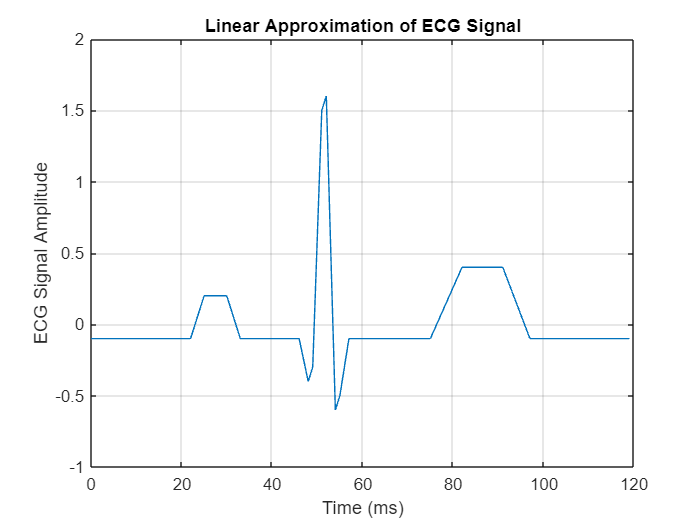

% Number of samples (data points)
num_samples = 120;

% Define total RR interval (in ms)
RR_interval = 830; % Total duration of one cycle in milliseconds

% Sampling time (ms per sample)
dt = RR_interval / num_samples; 

% Time vector for one cycle (in ms)
t = linspace(0, RR_interval, num_samples);

% Sample Index
sample_index = 0:length(y_i_1) - 1;  % Create an array of sample indices

% Initialize ECG signal
ecg_signal = zeros(1, num_samples);

% Define the key intervals (in ms)
P_duration = 80;          % P wave duration
PR_interval = 160;        % PR interval
QRS_duration = 80;        % QRS complex duration
ST_duration = 120;        % ST segment duration
T_duration = 160;         % T wave duration
TP_duration = RR_interval - (PR_interval + QRS_duration + ST_duration + T_duration);

% Split TP duration into two parts: before P wave and after T wave
TP_pre_duration = TP_duration / 2;  % TP before the P wave
TP_post_duration = TP_duration / 2; % TP after the T wave

% Define start times for each segment (in samples)
TP_pre_end = round(TP_pre_duration / dt);
P_start = TP_pre_end + 1;
P_end = P_start + round(P_duration / dt) - 1;
PR_end = P_end + round((PR_interval - P_duration) / dt);
QRS_end = PR_end + round(QRS_duration / dt);
ST_end = QRS_end + round(ST_duration / dt);
T_end = ST_end + round(T_duration / dt);
TP_post_end = num_samples;  % End of RR interval

% Create linear approximations for each segment

% TP segment (baseline before P wave)
ecg_signal(1:TP_pre_end) = -0.1;

% P wave divided into three parts
rise_duration = round((P_end - P_start + 1) / 3);  % 1/3 of the samples for rise
flat_duration = round((P_end - P_start + 1) / 3);  % 1/3 of the samples for flat top
fall_duration = P_end - P_start + 1 - (rise_duration + flat_duration);  % Remaining for the fall

% Linear rise from 0 to 0.2
ecg_signal(P_start:P_start + rise_duration - 1) = linspace(-0.1, 0.2, rise_duration);

% Stay at 0.2 for a few samples (flat top)
ecg_signal(P_start + rise_duration:P_start + rise_duration + flat_duration - 1) = 0.2;

% Linear fall from 0.2 to 0
ecg_signal(P_start + rise_duration + flat_duration:P_end) = linspace(0.2, -0.1, fall_duration);


% PR segment (flat)
ecg_signal(P_end+1:PR_end) = -0.1;



% QRS complex (sharp negative and positive deflections)
QRS_samples = round(QRS_duration / dt);  % Total samples for the QRS complex

% Divide into four segments
Q_duration = round(QRS_samples / 4);      % 1st segment (Q wave)
R_duration = round(QRS_samples / 4);      % 2nd segment (R wave)
S_duration = round(QRS_samples / 4);      % 3rd segment (S wave)
rise_duration = QRS_samples - (Q_duration + R_duration + S_duration);  % Remaining for the rise to baseline

% Negative deflection (Q)
ecg_signal(PR_end + 1:PR_end + Q_duration) = linspace(-0.1, -0.4, Q_duration);

% Positive spike (R)
ecg_signal(PR_end + Q_duration + 1:PR_end + Q_duration + R_duration) = linspace(-0.3, 1.5, R_duration);

% Small negative deflection (S)
ecg_signal(PR_end + Q_duration + R_duration + 1:PR_end + Q_duration + R_duration + S_duration) = linspace(1.6, -0.6, S_duration);

% Rise to baseline from -0.5 to -0.1
ecg_signal(PR_end + Q_duration + R_duration + S_duration + 1:QRS_end) = linspace(-0.5, -0.1, rise_duration);



% ST segment (flat, slightly elevated)
ecg_signal(QRS_end+1:ST_end) = -0.1;

% T wave divided into three parts
T_wave_length = T_end - ST_end;  % Total number of samples for the T wave
rise_duration = round(T_wave_length / 3);  % 1/3 of the samples for rise
flat_duration = round(T_wave_length / 3);  % 1/3 of the samples for flat top
fall_duration = T_wave_length - (rise_duration + flat_duration);  % Remaining for the fall

% Linear rise from 0.1 to 0.4
ecg_signal(ST_end + 1:ST_end + rise_duration) = linspace(-0.1, 0.4, rise_duration);

% Stay at 0.4 for a few samples (flat top)
ecg_signal(ST_end + rise_duration + 1:ST_end + rise_duration + flat_duration) = 0.4;

% Linear fall from 0.4 to 0
ecg_signal(ST_end + rise_duration + flat_duration + 1:T_end) = linspace(0.4, -0.1, fall_duration);


% TP segment (baseline after T wave)
ecg_signal(T_end+1:TP_post_end) = -0.1;

% Plot the linear ECG approximation
figure;
plot(sample_index, ecg_signal);
xlabel('Time (ms)');
ylabel('ECG Signal Amplitude');
ylim([-1, 2]);
title('Linear Approximation of ECG Signal');
grid on;

W_1 = wiener_opt_weights(ecg_signal, Noise_signal, 20);

% Filter x using wiener filter

filtered_signal_1 = filter(W_1, 1, x_);

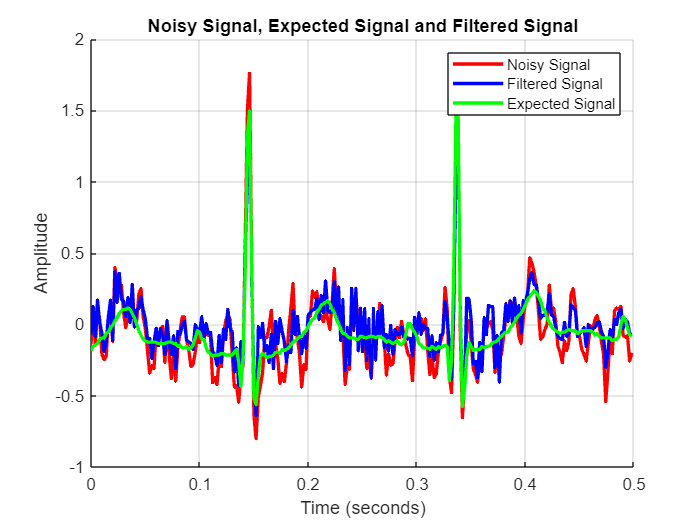

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(time(t_), filtered_signal_1(t_), 'b-', 'DisplayName', 'Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(time(t_), y_i(t_), 'g-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

% Find the optimum order filter
MSEs_1 = zeros(1, 500);  % Preallocate array for efficiency
for i = 1:500
    W__ = wiener_opt_weights(ecg_signal, Noise_signal, i);
    filtered_signal__ = filter(W__, 1, x_);
    MSEs_1(i) = mean((y_i - filtered_signal__).^2);  % Store MSE in the i-th location
end
disp(MSEs_1);

    0.0211    0.0210    0.0209    0.0205    0.0196    0.0187    0.0185    0.0185    0.0183    0.0176    0.0171    0.0171    0.0172    0.0170    0.0173    0.0164    0.0164    0.0167    0.0164    0.0182    0.0159    0.0162    0.0163    0.0164    0.0162    0.0158    0.0158    0.0158    0.0157    0.0156    0.0155    0.0154    0.0154    0.0156    0.0153    0.0150    0.0149    0.0149    0.0154    0.0150    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0144    0.0144    0.0145    0.0145    0.0145    0.0145    0.0145    0.0142    0.0142    0.0142    0.0142    0.0142    0.0141    0.0141    0.0141    0.0141    0.0141    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0141    0.0141    0.0141    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0142    0.0143    0.0143    0.0143    0.0143    0.0143    0.0143    0.0144

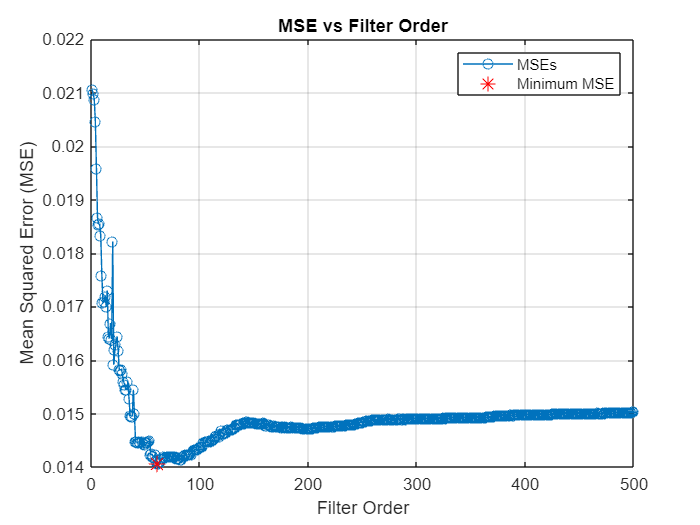

% Find the minimum value in MSEs and its index
[minMSE_1, minIndex_1] = min(MSEs_1);

% Plot MSEs
figure;
plot(1:500, MSEs_1, '-o');  % Plot MSEs against iterations (1 to 100)
xlabel('Filter Order');
ylabel('Mean Squared Error (MSE)');
title('MSE vs Filter Order');
grid on;

% Highlight the minimum MSE on the plot
hold on;
plot(minIndex_1, minMSE_1, 'r*', 'MarkerSize', 10);  % Red star at the minimum point
legend('MSEs', 'Minimum MSE');
hold off;


% Display the minimum MSE and its index
disp(['Minimum MSE: ', num2str(minMSE_1), ' at iteration ', num2str(minIndex_1)]);

Minimum MSE: 0.014062 at iteration 61


M_optimum_1 = 61;
W_optimum_1 = wiener_opt_weights(ecg_signal, Noise_signal, M_optimum_1);
fvtool(W_optimum_1, 1);

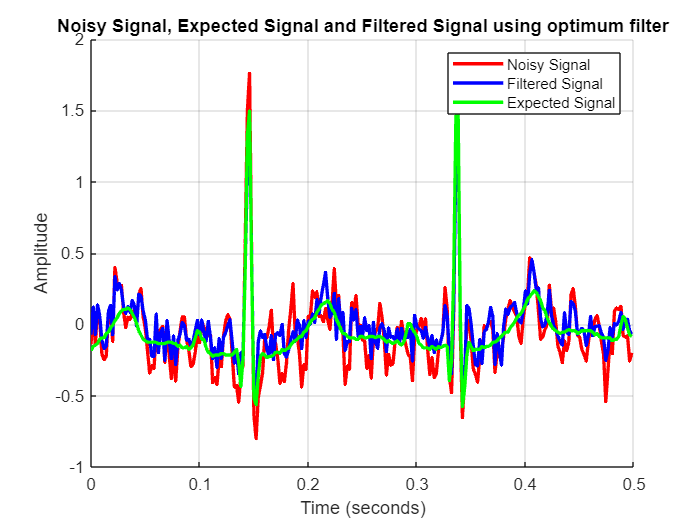

filtered_signal_opt_1 = filter(W_optimum_1, 1, x_);

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(time(t_), filtered_signal_opt_1(t_), 'b-', 'DisplayName', 'Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(time(t_), y_i(t_), 'g-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal using optimum filter');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

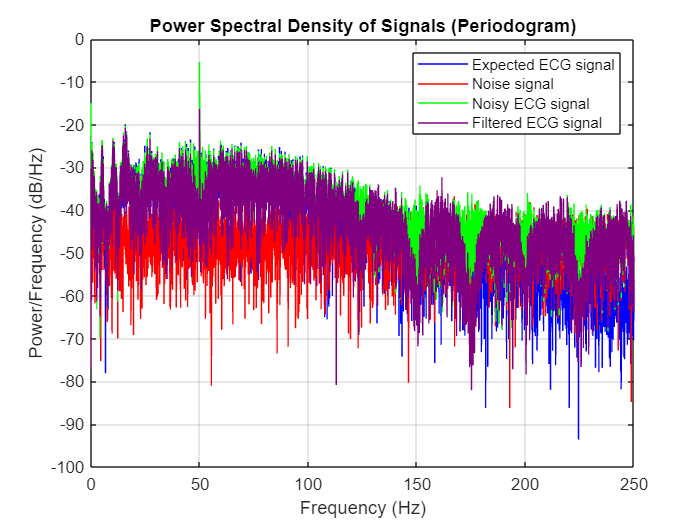

% Calculate the periodogram (PSD) for each signal
[psd1_1, f1_1] = periodogram(y_i, [], [], Fs);
[psd2_1, f2_1] = periodogram(only_noise, [], [], Fs);
[psd3_1, f3_1] = periodogram(x, [], [], Fs);
[psd4_1, f4_1] = periodogram(filtered_signal_opt_1, [], [], Fs);

% Plot all PSDs in the same figure
figure;
plot(f1_1, 10*log10(psd1_1), 'b', 'DisplayName', 'Expected ECG signal');  % PSD of signal 1 in blue
hold on;
plot(f2_1, 10*log10(psd2_1), 'r', 'DisplayName', 'Noise signal');  % PSD of signal 2 in red
plot(f3_1, 10*log10(psd3_1), 'g', 'DisplayName', 'Noisy ECG signal');  % PSD of signal 3 in green
plot(f4_1, 10*log10(psd4_1), 'Color', [0.5 0 0.5], 'DisplayName', 'Filtered ECG signal');  % PSD of signal 3 in green

% Customize the plot
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density of Signals (Periodogram)');
legend;
grid on;
hold off;

### 1.2 Frequency domain implementation of the Wiener filter

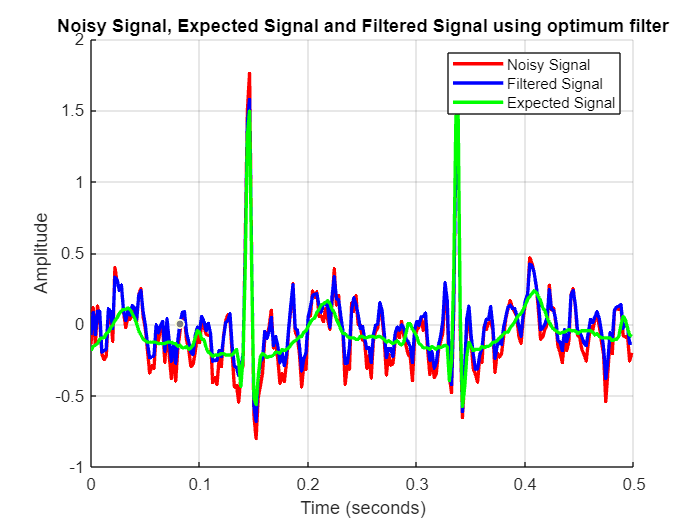

points = length(x);
W_f = wiener_freq_weights(y_i_1, Noise_signal, points);
freq_filtered_signal = filter_wiener_freq(x_, W_f, points);

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(time(t_), freq_filtered_signal(t_), 'b-', 'DisplayName', 'Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(time(t_), y_i(t_), 'g-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal using optimum filter');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

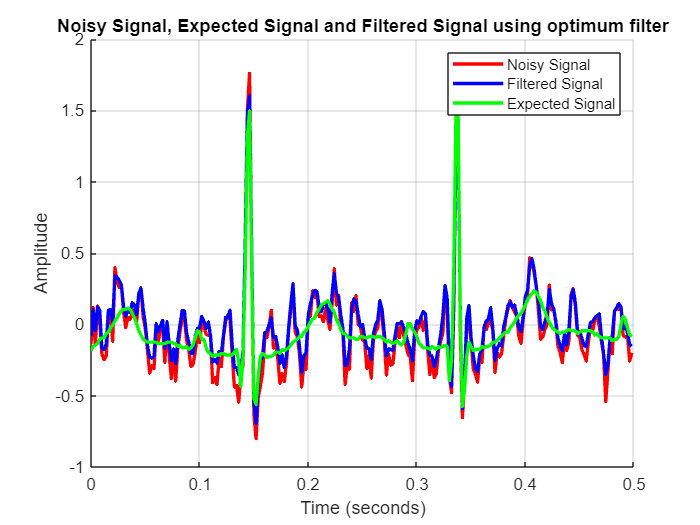

W_f_1 = wiener_freq_weights(ecg_signal, Noise_signal, points);
freq_filtered_signal_1 = filter_wiener_freq(x_, W_f_1, points);

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 2);  % Noisy signal in red dashed line
plot(time(t_), freq_filtered_signal_1(t_), 'b-', 'DisplayName', 'Filtered Signal', 'LineWidth', 2);  % Filtered signal in solid blue line
plot(time(t_), y_i(t_), 'g-', 'DisplayName', 'Expected Signal', 'LineWidth', 2)
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signal using optimum filter');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

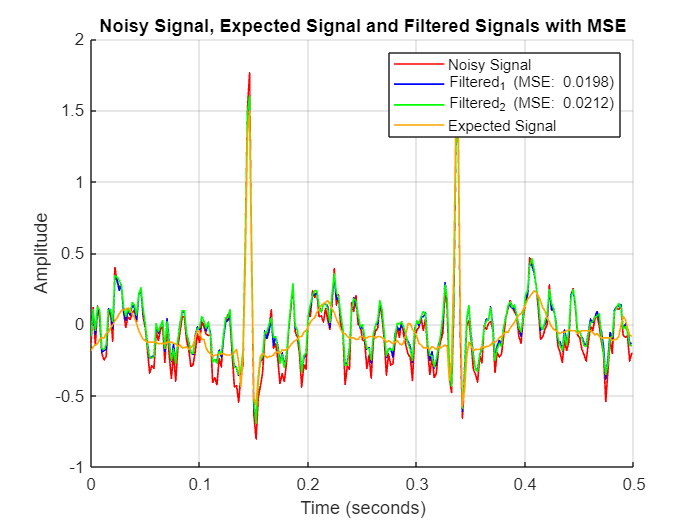

mean_squared_error_1 = mean((y_i - freq_filtered_signal).^ 2);
mean_squared_error_2 = mean((y_i - freq_filtered_signal_1).^ 2);

t_ = 1:250;
% Plotting the noisy signal, expected signal, and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), x(t_), 'r-', 'DisplayName', 'Noisy Signal', 'LineWidth', 1);  % Noisy signal in red solid line

% Add MSE to the legend for Filtered_1 and Filtered_2
plot(time(t_), freq_filtered_signal(t_), 'b-', ...
    'DisplayName', ['Filtered_1 (MSE: ' num2str(mean_squared_error_1, '%.4f') ')'], 'LineWidth', 1);  % Filtered signal 1 with MSE

plot(time(t_), freq_filtered_signal_1(t_), 'g-', ...
    'DisplayName', ['Filtered_2 (MSE: ' num2str(mean_squared_error_2, '%.4f') ')'], 'LineWidth', 1);  % Filtered signal 2 with MSE

plot(time(t_), y_i(t_), 'color',[1, 0.6471, 0], 'DisplayName', 'Expected Signal', 'LineWidth', 1);  % Expected signal

xlabel('Time (seconds)');
ylabel('Amplitude');
title('Noisy Signal, Expected Signal and Filtered Signals with MSE');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

### 1.3 Effect on non-stationary noise on Wiener filtering

n_50  = 0.2 * sin(2 * pi * 50 * time(1 : length(y_i)/2));
n_100 = 0.2 * sin(2 * pi * 100 * time((length(y_i)/2) + 1 : length(y_i)));
New_noise = [n_50, n_100];  % Concatenate horizontally, not vertically

new_signal = y_i + New_noise;  % Add the noise to the original signal

% Make the mean of the signal zero
new_signal_1 = new_signal - mean(new_signal);  % Subtract the mean of the new signal


% Filter in time domain
filtered_new_signal = filter(W_optimum, 1, new_signal_1);

% Filter in freq domain
filtered_new_signal_1  = filter_wiener_freq(new_signal_1, W_f, points);

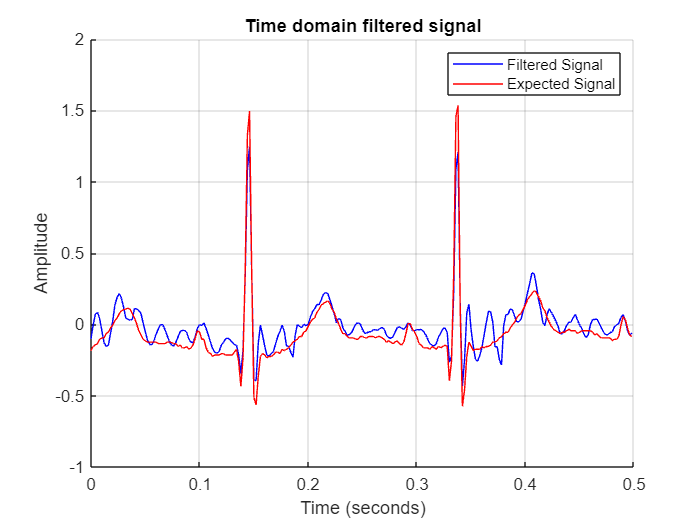

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), filtered_new_signal(t_), 'b-', 'DisplayName', 'Filtered Signal');  
plot(time(t_), y_i(t_), 'r-', 'DisplayName', 'Expected Signal')
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Time domain filtered signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

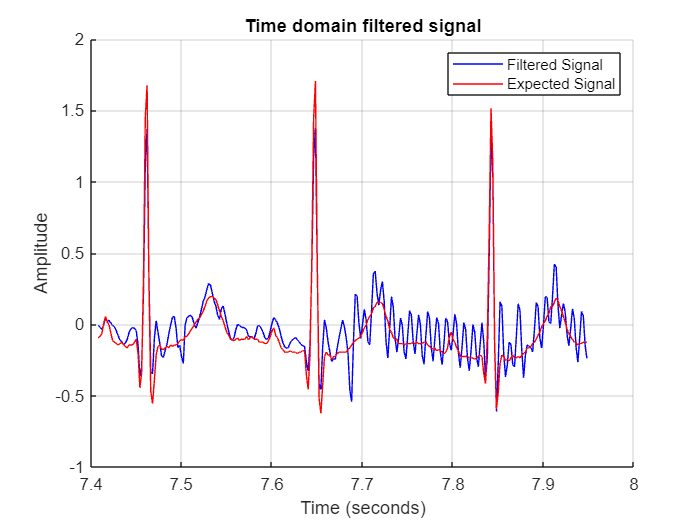

t_ = 3705:3975;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), filtered_new_signal(t_), 'b-', 'DisplayName', 'Filtered Signal');  
plot(time(t_), y_i(t_), 'r-', 'DisplayName', 'Expected Signal')
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Time domain filtered signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

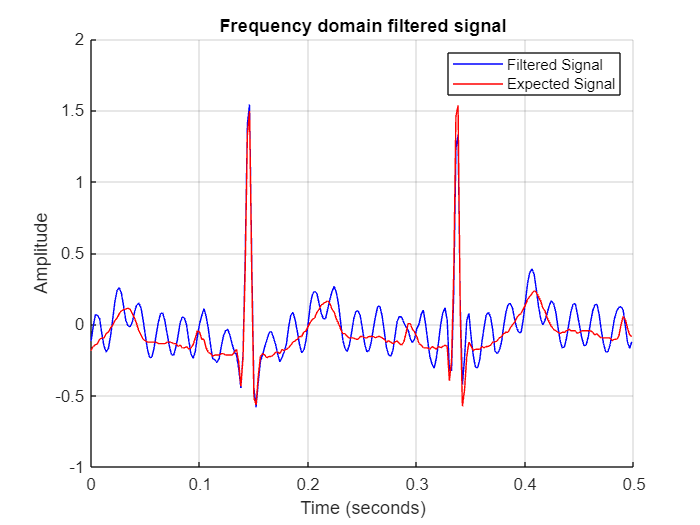

t_ = 1:250;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), filtered_new_signal_1(t_), 'b-', 'DisplayName', 'Filtered Signal');  
plot(time(t_), y_i(t_), 'r-', 'DisplayName', 'Expected Signal')
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Frequency domain filtered signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot

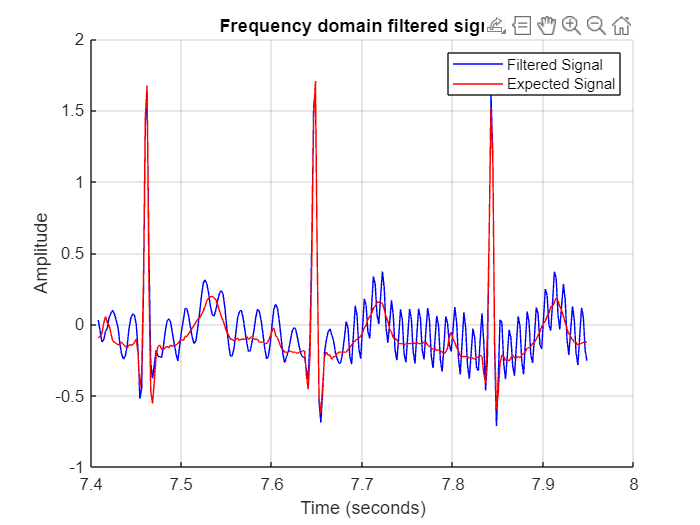

t_ = 3705:3975;
% Plotting the noisy signal, expected signal and filtered signal
figure;
hold on;  % Keep the current plot
plot(time(t_), filtered_new_signal_1(t_), 'b-', 'DisplayName', 'Filtered Signal');  
plot(time(t_), y_i(t_), 'r-', 'DisplayName', 'Expected Signal')
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Frequency domain filtered signal');
legend('show');  % Show legend
grid on;  % Add grid for better visibility
hold off;  % Release the plot